% MANUALLY LOAD .mat FILES FOR INDIVIDUAL ANALYSIS

% CALC'S FOR LATER
RoundXpts = round(abs(yPickedPts)); %switch x & y
RoundYpts = round(abs(xPickedPts));


clear PTSdfof % pulling fluoresence data from just the points picked in threshPassAnalysis script
for i = 1:length(xPickedPts)
    PTSdfof(i,:,:) = onsetDf(RoundXpts(i),RoundYpts(i),:,:);
end
display('size of PTSdfof is: ')
size(PTSdfof)


% x axis
% plot each graph for dfof traces for each point as subplots on the same main plot
clear frameNum
frameNum = 1:size(onsetDf,3); % making the x axis frame number - 3rd dimension (frames) of onsetDf 


% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% need to make vectors with contrast values 
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    % note: stim details contains info (incl. contrast values) for every 
    % possible condition. It is NOT ordered by trial.
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

% note: trial cond is a list of indicies for tc/stimdetails.targContrast.
% These indicies *are* ordered by trial
% so now, by using trialCond to index into tc, we can get a list of target
% contrasts in the order that they were presented:

conOrderedByTrial = con(trialCond); % use trial cond to index into vector of 
% target contrast value for that condition during each trial, save in new
% vector 'conTrial' that is a list of trial conditions ordered by trial

uniqueContrasts = unique(con); % gets a list of the contrast value options, 
% so we know how many contrasts to loop over


% DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% need to make vectors with duration values
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    % note: stim details contains info (incl. contrast values) for every 
    % possible condition. It is NOT ordered by trial.
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

% note: trial cond is a list of indicies for rown in stimdetails - with this you can index what stim conditions (duration, contrast etc) were displayed each trial
% These indicies *are* ordered by trial
% so now, by using trialCond to index into d, we can get a list of stimulus in the order that they were presented:

durOrderedByTrial = dur(trialCond); % save in new vector that is a list 
% of trial conditions ordered by trial

% from imagingThresholdPassive: 
% trials = abs(fcTrial)==contrasts(c) & tcTrial ==tcontrasts(c2);
% ^ this is done inside for loops
% fcTrial is the list of trials at the order presented

% gets a list of the duration value options, so we know how many durations to loop over
uniqueDurations = unique(dur); 


% select picked points from baseline image (NO)

% I don't think this makes sense, because I *don't* want just one baseline value for each point -
% I need the baseline value to be based off of what trials i am averaging over in any given loop,
% whereas meanBaselineImage was created in baselineGraphical1 for highest con trials

% % we only want one baseline value for each point, so using meanBaselineImage makes sense
% clear meanBaselineImagePTS % pulling fluoresence data from just teh points picked in threshPassAnalysis script
% for i = 1:length(xPickedPts)
%     meanBaselineImagePTS(:,:,i) = meanBaselineImage(RoundXpts(i),RoundYpts(i)); 
% end
% meanBaselineImagePTS = squeeze(meanBaselineImagePTS);
% meanBaselineImagePTS = meanBaselineImagePTS';
% display('meanBaselineImagePTS: ')
% size(meanBaselineImagePTS)
      

reigonsTitle = {'V1','HVA1','HVA2','HVA3','HVA4'};
durationsTitle = {'16ms','33ms','66ms','133ms','266ms'};
contrastsTitle = {'0%','3%','6.25%','12.5%','25%','50%','100%'};

% CONTRAST FIGURES

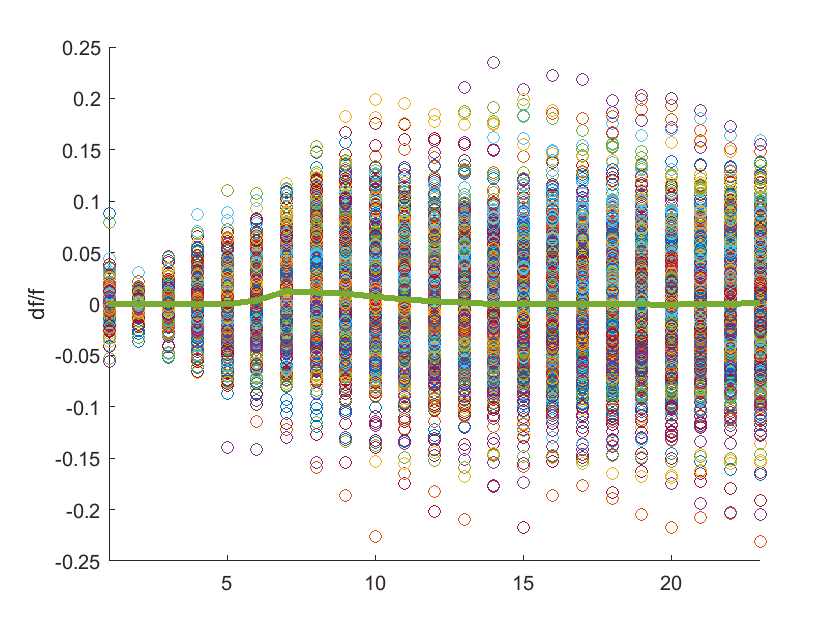

% BASELINE TEST
% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% (better than following version)

% what am I trying ot get the basline of here? Every trial? 
% For every trial, subtract the mean activity of the 1st 4 frames?

clear recomboOnePtAllFramesAllTrialMinusMeanBase
clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

figure % make one figure for all subplots

%for i = 1:length(xPickedPts) % for each point
clear i
for i = 1
    
    %subplot(2,3,i) % make a subplot
    
    clear onePtAllFramesAndTrials % new var each point
    clear recomboOnePtAllFramesAllTrialMinusMeanBase
    clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
    % collect all trials over all frames for the ith point
    onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
    onePtAllFramesAndTrials = onePtAllFramesAndTrials'; 
    
    % for every trace, subtract the baseline value at that point from each frame value
    
    clear tr % for each trial in onePtAllFramesAndTrial
    for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
        % getting TRIAL VECTOR
        clear onePtAllFramesOneTrial % make new var for each trial
        % index into each trace/vector & save as variable
        onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
       
        % getting MEAN BASEline VALUE for each TRIAL
        % new mean baseline frame each time
        
        clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
        % collect 4 baseline frames for tr-th ith trial
        allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
        clear mean4baseFramesOnePtOneTrial
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
        
        % BASEline CORRECTion of TRIAL VECTOR
        
        % new baseline-corrected trace for each trial
        % calulate the baselined trace for the ith trial
        onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
        % collect CORRECTed TRIAL VECTORS in matrix
        % save each tr-th baselined trace in a matrix for plotting mean later
        % (only clear this outside the loop for each point)
        recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
        
        clear x_axis
        x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
        % plot one baseline corrected trace at a time
        %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase) % plot dfof the first point vs frames for each trial   
        % hold on because we're doing it for every trial on the same plot
        
        scatter(x_axis,onePtAllFramesOneTrialMinusMeanBase)
        
        hold on
        
    end % stop looping thorugh trials

    % need to plot the mean for BASELINED trace vector
    
    % get mean baselined trace across all trials
    meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
    plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
    ylim([-0.25 0.25]) 
    xlim([1 length(x_axis)])
    ylabel('df/f')
    
    ax = gca;
    x.XTick = [1:1:length(x_axis)];
    
end

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% (better than following version)

figure % make one figure for all subplots

for i = 1:length(xPickedPts) % for each point
    
    clear onePtAllFramesAndTrials
    clear baselineSubtOnePtAllFramesAndTrial
    
    subplot(2,3,i) % make a subplot
    
    % collect all trials over all frames for the ith point
    onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
    
    % for every trace, subtract the baseline value at that point from each frame value
    
%     clear tr % for each trial in onePtAllFramesAndTrial
%     for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
%         % index into each trace/vector & save as variable
%         onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
%         
%         clear f
%         for f = 1:length(onePtAllFramesOneTrial) % for each frame of the trial
%             % subtract the baseline value for that point from the fth frame of the tr-th trial
%             % & save each result in row 1 column f of new variable
%             baselineSubtOnePtAllFramesAndTrials(1,f) = onePtAllFramesOneTrial(f)-meanBaselineImagePTS(i); 
%         end
%         
%         % collect each baselined trial vector for taking the mean later:
%         allBaselineSubtOnePtAllFramesAndTrials(tr,:) = baselineSubtOnePtAllFramesAndTrials;
%         
%         % now that I've got the list of baselined values for 1 trial,
%         % plot that trial, hold on, and keep doing it over again until
%         % you're done with trials and you reach the next point
%         
        clear x_axis
        x_axis = 1:size(onePtAllFramesAndTrials,2); % length of frames
        plot(x_axis,onePtAllFramesAndTrials) % plot dfof the first point vs frames for each trial
   
%         hold on % keep doing until done with ith trials
%         
%     end 
    
    hold on
    
    meanOnePtAllFramesAndTrials = mean(onePtAllFramesAndTrials,1); % take mean across trials
    plot(x_axis,meanOnePtAllFramesAndTrials,'linewidth',4)
    ylim([-0.15 0.3]) 
    xlim([1 length(x_axis)])
    ylabel('df/f')
    
end

% clear meanOnePtAllFramesAndTrials
% 
% hold on % now plot the mean for each point on the 6th subplot
% 
% clear i
% for i = 1:length(xPickedPts)
%     subplot(2,3,6)
%     
%     onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); % collect all trials over all frames for the ith point
%     onePtAllFramesAndTrials = onePtAllFramesAndTrials';
%     meanOnePtAllFramesAndTrials = mean(onePtAllFramesAndTrials,1);
%     
%     plot(x_axis,meanOnePtAllFramesAndTrials,'linewidth',4)
%     
%     hold on
%     
%     title('mean each visual area')
%     ylim([-0.15 0.28])
%     xlim([0 length(x_axis)])
%     ylabel('df/f')
%     xlabel('frames')
%     
% end


% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% SAME AS BOVE BUT BY DURATION & BASELINE SUBTRACT
% one figure for each visual area, subplts are duration
% take either just the highest contrast or the mean over all of them


for i = 1:length(xPickedPts) % for each point
    
    figure % one figure for each visual area
    suptitle(sprintf('%s', reigonsTitle{i}));
    
    c = 7; % highest contrast only
    
    for d = 1:length(uniqueDurations)
    
        clear Dth7CthTrials
        Dth7CthTrials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrial(2,:) == uniqueDurations(d);

        % on each subplot we want to plot df/f vs frames for each dth trial, for the ith point
        clear onePtAllFramesDth7CthTrial
        onePtAllFramesDth7CthTrials = squeeze(PTSdfof(i,:,Dth7CthTrials)); % collect all trials over all frames for the ith point
        
        %onePtAllFramesDth7CthTrials = onePtAllFramesDth7CthTrials'; % get in trials x frames
        
        % now we need to subtract the baseline , but this time off of each trial rather than the mean trace
        
        % the baseline values are defined in the beginnig of this script,
        % saved as 'minusBaselinePTSdfof'
        
        % subtracting the ith dth baseline value from each df/f at each frame, for the t-th trial
        clear t
        for t = 1:length(onePtAllFramesDth7CthTrials) % can't use dth trials b/cause it's 1's & zeros for *every* trial
            
            % for each trial, take all frames, store in 1 x #frames vector
            clear oneTrialOnePtAllFramesDthTrial
            oneTrialOnePtAllFramesDthTrial = onePtAllFramesDthTrials(t,:);
            
            % now subtract the ith baseline value from each frame in tha vector
            % the baseline doesn't need to be calulated per duration, because it's the activity *before* the stim comes on
            
            % this should return a frames x trials vector
            clear onePtAllFramesDthTrialsMinusBaseline
            onePtAllFramesDthTrialsMinusBaseline = oneTrialOnePtAllFramesDthTrial-meanBaselineImagePTS(i);
            
            % now for each collection of baselined dth trials, plot on the same subplot
            subplot(2,3,d) % make a subplot for each duration
            
            x_axis = 1:length(onePtAllFramesDthTrialsMinusBaseline); % x axis is frames
           % plot(x_axis,onePtAllFramesDthTrialsMinusBaseline)
            
            % for plotting the mean later: store this new baseline trace vector in a new matrix for the dth trials only          
            onePtAllFramesAllDthTrialsMinusBaseline(t,:) = onePtAllFramesDthTrialsMinusBaseline;
            
            hold on
            
        end
        
        hold on
            
            % plot the mean of all trial traces over the same subplot:
            clear meanOnePtAllFramesAllDthTrialsMinusBaseline
            meanOnePtAllFramesAllDthTrialsMinusBaseline = mean(onePtAllFramesAllDthTrialsMinusBaseline,1);
            plot(x_axis,meanOnePtAllFramesAllDthTrialsMinusBaseline,'linewidth',1)
            
            clear st
            st = title(sprintf('%s', durationsTitle{d}));
            
            xlim([0 length(x_axis)])
            ylim([-0.025 0.1])
        
    end 
    
end

% plot mean across trials for each point at each duration? havent't I done that? or no?
% hold on % now plot the mean for each point on the 6th subplot
% for j = 1:length(xPickedPts)
%     subplot(2,3,6)
%     plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',1) % here's plotting the mean over trials (dimension 2 in PTSdfof)
%     title('mean each visual area')
%     ylim([-0.0225 0.0225]) 
%     xlim([0 length(frameNum)])
%     ylabel('df/f')
%     xlabel('frames')
%     hold on
% end


% DFOF VS FRAMES, TRACE = CONTRAST, SUBPLOT = POINT **W/BASELINE SUBTRACTION
% now we're going to plot one figure, and each subplot is for one point with
% several traces - one for each contrast. Each trace is dfofof for that point, over over frames, for one contrast

figure % only making 1 figure
%suptitle(sprintf('EE81LT: df/f vs frames for each contrast at each point'))   
clear i
for i = 1:length(xPickedPts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    
    % on each subplot plot the mean dfof across trials vs frames, w/a trace for each contrast
    % but first, subtract the baseline from each trace

    clear c
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear cthTrials
        cthTrials = conOrderedByTrial == uniqueContrasts(c); % get trials at this contrast
        
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
        % 1 x #trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frames
        
        % getting baseline image
        for b = 1:length(baselineIdx) % baselineIdx defined in baseline script

            eachbaselineFrameOnsetDf = onsetDf(:,:,baselineIdx(b),cthTrials);
            eachbaselineFrameOnsetDfMeanTrials = mean(eachbaselineFrameOnsetDf,4);
            allbaselineFrames(:,:,b) = eachbaselineFrameOnsetDfMeanTrials;
        
        end
        
        meanBaselineImage =  mean(allbaselineFrames,3);
        
        % subtract baseline value from each cell in meanOverTrialsPTSdfof
        clear minusBaselinePTSdfof
        clear j
        for j = 1:length(meanOverTrialsPTSdfof) % for each df/f value in the mean @ one point traces
            
            minusBaselinePTSdfof(j) = meanOverTrialsPTSdfof(j)-meanBaselineImagePTS(i); % subtract the baseline at that point
        
        end 
        
        %STDEV
        clear err
        err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
        % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
        
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
        
        errorbar(frameNum,minusBaselinePTSdfof,err, 'linewidth',1)
        %plot(frameNum,meanOverTrialsPTSdfof, 'linewidth',1)
        ylim([-0.02 0.045]) 
        xlim([0 length(frameNum)])
        ylabel('df/f')
        xlabel('frames')
        hold on
        
    end 
    legend('0','0.03','0.063','0.125','0.25','0.5','1')
    % collect all the matricies for all the i-th points
%     sqForGroupMeanOverTrialsPTSdfof = squeeze(forGroupMeanOverTrialsPTSdfof);
%     allPtsMeanOverTrialsPTSdfof(:,:,i) = sqForGroupMeanOverTrialsPTSdfof;
    
%     % now for each contrast figure, I want the 6th subplot to be the
%     % mean trace for each point across all contrasts (this was done in an earlier figure but want it here too)
%     hold on
%     for j = 1:length(xPickedPts)
%         subplot(2,3,6)
%         plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',2) % here's plotting the mean over trials (dimension 2 in PTSdfof)
%         title('mean d/f each point')
%         ylim([-0.05 0.05]) 
%         xlim([0 length(numFrames)])
%         ylabel('df/f')
%         xlabel('frames')
%         hold on
%         end
%         legend('HVA_1','HVA_2','HVA_3','V1', 'control')
end 


% LATENCY 
% find the max, and then the frame the max is at

% lets pick 

clear i
% 7 contrasts for x axis
x_axis = [1 2 3 4 5 6 7];
figure;
suptitle('EE18LT: latency vs contrast')
for i = 1:length(xPickedPts)
    clear maxContRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    clear contLatencyInFrames
    clear c
    for c = 1:length(uniqueContrasts)
        
        clear meanOverTrialsPTSdfof
        clear maxOverFramesTrialsPTSdfof 
        clear latencyInFrames
        clear cthTrials
        
        %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = conOrderedByTrial == uniqueContrasts(c); 
        
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        latencyInFrames = find(meanOverTrialsPTSdfof == maxOverFramesTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        contLatencyInFrames(1,c) = latencyInFrames; % one row, each 7 columnns  
        
        % saving each cth latency value 
        contMaxOverFramesTrialsPTSdfof(1,c) = maxOverFramesTrialsPTSdfof;
        
        % STDEV
        % we only want the frames for the latencies for our max values, but still need stdev over trials
        %latTrials = latencyInFrames
        stdErrConLatOverTrials(1,c) = std(PTSdfof(i,latencyInFrames,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    convertFrames2Sec = 0.1*contLatencyInFrames;
    
    % for GROUP
    % collect all the latency for each contrast over all trials into a 2-D variable
    % with the cells as latency, 1st dimension as points (rows), the second dim as contrasts
    % the below is 5 x 7 
     %allPtsConvertFrames2Sec(i,:) = convertFrames2Sec;
     
    % still w/in the points for loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     % scatter(x_axis,convertFrames2Sec)
     errorbar(x_axis,convertFrames2Sec,stdErrConLatOverTrials,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     ylim([0 6]) 
     xlim([0 8])
     xlabel('contrasts')
     ylabel('seconds')
     
end


% CRF w/ PEAK (MEAN @ LATENCY) --> determined by looking at latency.. just taking mean at these frames, not using max function
% CRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 7:1:9;
contrastValues = [0 0.03 0.063 0.125 0.25 0.5 1];

figure
clear i
suptitle('Contrast Response Functions for Each Visual area')
for i = 1:length(xPickedPts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contStdErr
    
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    
    clear c
    for c = 1:length(uniqueContrasts)
        
        clear cthTrials
        %cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = conOrderedByTrial == uniqueContrasts(c);  
        
        % CRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthTrials));
        sq5FramesOverTrialsPTSdfof = sq5FramesOverTrialsPTSdfof;
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th CRF value for this point
        % creates 1 x 7 (contrasts)
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr;
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue') 
    ylim([-0.02 0.05]) 
    xlim([0, 8])
    
    clear xt
    xt={'0'; '3' ; '6' ; '1' ; '25' ; '50'; '100'} ; 
    set(gca,'xtick',1:7); 
    set(gca,'xticklabel',xt);
    
    title(reigonsTitle{i})
     ylabel('df/f')
     xlabel('contrast (%)')
    
end 

%savefig('G6H277RT_020421_CRF_imThreshPass')

% DISTRIBUTION
% Now need to plot the distribution of amplitude values at t = 15, for each contrast and each point

pickFrame = 15; % based on latency plots

for i = 1:length(xpts) % for each point make a figure
    figure 
    suptitle('Frequency of Response Magnitudes for Each Contrast, V1')
    %suptitle(sprintf('point = %0.1d',i))
    
    % making the subplots for each contrast
    for c = 1:length(uniqueContrasts) % for each contrast
        
        clear sqOneFrameOverTrialsPTSdfof
        clear cthTrials
        
        cthConOrderedByTrialMeetCriteria = conOrderedByTrial(idxOnsetsMeetBothCriteria);
        cthTrials = cthConOrderedByTrialMeetCriteria == uniqueContrasts(c);
        
        % clear contSqOneFrameOverTrialsPTSdfof % need here since each c-th vector is different length
       
        % taking the i-th point, frame 15, c-th trials & squeezing a singleton out
        % dF/F for at one point for all 15th frames at this contrast
        sqOneFrameOverTrialsPTSdfof = squeeze(PTSdfof(i,pickFrame,cthTrials))'; % for the i-th point,
        % and the c-th contrast, store all trials at  frame 15
      
        % CANT do: store output vectors for each contrast
        % contSqOneFrameOverTrialsPTSdfof(:,:,c) = sqOneFrameOverTrialsPTSdfof; % 1x7, mean dfof (at frame 15) for each contrast
        
        % the problem here is that every vector 'sqOneFrame..' is a different length, so can't 'collect'
        % Better to just plot directly on the subplot here
        
        subplot(2,4,c) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',contrasts(c)))
        
        numBins = sum(cthTrials);
        histogram(sqOneFrameOverTrialsPTSdfof)
        xlabel('df/f @ t = 1.5s')
        %ylabel('% of trials')
        ylim([0 32.5])
        xlim([-0.15 0.3])
        
%         hold on
%         plot(allPtsContMeanOneFrameOverTrials(1,c),0, 'r*') % mean df/f for 1st point, c-th contrast @ frame 15
        
        hold on  
        
    end
   
        % once you've got all 7 (contrast) traces (all trials), get rid of the singleton dimension (frame 15)
        %  sqContSqOneFrameOverTrialsPTSdfof = squeeze(contSqOneFrameOverTrialsPTSdfof)';
end

%savefig('G6H277RT_020421_ConHisto')

% DURATION


% DFOF VS FRAMES, TRACE = DURATION, SUBPLOT = POINT
% now we're going to plot one figure, and each subplot is for one point with
% several traces - one for each duration. Each trace is dfofof for that point, over over frames, for one duration

figure % only making 1 figure
% suptitle(sprintf('EE81LT: df/f vs frames for each contrast at each point'))   
clear i
for i = 1:length(xpts) % for each point
    subplot(2,3,i) % give each point it's own subplot
    % on each subplot plot the mean dfof across trials, vs frames
    
    % now on each subplot/for each point we're going 
    % to plot the mean across trials for each duration, for each point
  
    for d = 1:length(uniqueDurations) 
        
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
 
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1 by # frames variable that has dfof of one point averaged across trials
        % at the d-th contrast, for all frames
        
        %STDEV
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(length(dthTrials)); % across all trials = 3rd dim
        % stdOverTrialsPTSdfof = (std(meanOverTrialsPTSdfof)/sqrt(trials);
        % err = stdOverTrialsPTSdfof*ones(size(meanOverTrialsPTSdfof)); % b/c just one stdev for whole trace across trials at the c-th contrast
        
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
        
        errorbar(frameNum,meanOverTrialsPTSdfof,err, 'linewidth',1)
        % plot(frameNum,meanOverTrialsPTSdfof, 'linewidth',1)
        ylim([-0.1 0.1]) 
        xlim([0 51])
        ylabel('df/f')
        xlabel('frames')
        hold on
        
    end 
   % legend('16 ms','33 ms', ','15','30','60','100000')
    
    % now  I want the 6th subplot to be the
    % mean trace for each point across all durations 
    hold on
    for j = 1:length(xpts)
        subplot(2,3,6)
        plot(mean(squeeze(PTSdfof(j,:,:)),2),'linewidth',2) % here's plotting the mean over trials (dimension 2 in PTSdfof)
        ylim([-0.05 0.05]) 
        xlim([0 51])
        ylabel('df/f')
        xlabel('frames')
        hold on
        end
        legend('HVA_1','HVA_2','HVA_3','V1', 'control')
end 

% LATENCY for DURATION
% plot latency @ df/f peak for each duration for each point
% set up points loop then duration loop w/in it

% 7 durations for x axis
x_axis = [1:length(uniqueDurations)];
figure;
% suptitle('EE18LT: latency vs contrast')
for i = 1:length(xpts)
    clear maxDurRespOverFramesTrialsPTSdfof % clear this so the mean dfof for each points dont write over each other, plotting nonsense
    clear durLatencyInFrames
    clear err
    for d = 1:length(uniqueDurations)
        clear trials
        clear maxOverFramesTrialsPTSdfof 
        clear latencyInFrames
        clear dthTrials
        
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
     
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        maxOverFramesTrialsPTSdfof = max(meanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that duration, find the frame (column index) it corresponds to
        latencyInFrames = find(meanOverTrialsPTSdfof == maxOverFramesTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect both latency values into vectors that should be the same length as maxDurRespOverFramesTrialsPTSdfof 
        durLatencyInFrames(1,d) = latencyInFrames; % one row, columns = # durations
        
        % STDEV
        % we only want the frames for the latencies for our max values, but still need stdev over trials
        err(1,d) = std(PTSdfof(i,latencyInFrames,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim % sum not length
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to seconds, for each point
    format short g
    convertFrames2Sec = 0.1*durLatencyInFrames;
    
    % for GROUP
    % collect all the latency for each contrast over all trials into a 2-D variable
    % with the cells as latency, 1st dimension as points (rows), the second dim as contrasts
    % the below is 5 x 7 
     allPtsConvertFrames2Sec(i,:) = convertFrames2Sec;
     
    % still w/in the points for loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     % scatter(x_axis,convertFrames2Sec)
     errorbar(x_axis,convertFrames2Sec,err,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     ylim([0 6]) 
     xlim([0 8])
     %xlabel('duration')
     %ylabel('seconds')
     
end


% DRF -  Duration Response Function over frames 14-16

% want to plot response vs duration for each duration and in each visual area

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;
durationValues = [1 3 5 15 30 60 100000];

figure % make figure outside i loop & all others b/c each point is a subplot w/DRF for that point
suptitle('Duration Response Function for each Point') 
for i = 1:length(xpts) % for each point
    
     clear sq5FramesOverTrialsPTSdfof
     clear meanOverFramesSq5FramesOverTrialsPTSdfof
     clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
     clear durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
     clear durStdErr
    
    for d = 1:length(uniqueDurations)
       
        % collecting trials at the d-th duration
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);
        
        % DRF VALUES for each duration, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,dthTrials));
        
        % take the mean over frames
        % returns 1 x # trials
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th DRF value for this point
        % creates 1 x # durations
        durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each DRF point calulated above
        % (one err value for each duration)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr; % store stdErr for each duration in a new 
        % vector where each err is in the first row and c-th column
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1:length(uniqueDurations)];
    errorbar(x_axis,durMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue') 
    ylim([-0.02 0.09]) 
    ylabel('df/f')
    xlim([0, 8])
    %xticklabels({'0.016','0.05','0.083','0.25','0.5','1','1667'})
    xlabel('seconds')
    
    %% ylabel('df/f')
    %% xlabel('contrast')
    
end 

%savefig('G6H277RT_020421_DRF')

% DISTRIBUTION

%% -- looks like prior time I plotted the distribution of
% dfof amplitude values at t = 1.5 sec. But now I want
% to plot dfof averaged across 3 frames. I calulated this
% before for the DRF. Will use that vaiable instead of 
% indexing anew here?

% Now need to plot the distribution of amplitude values at t = 15, for each contrast and each point

frameRange = 14:16;

for i = 1:length(xpts) % for each point
    
    figure % make figure inside i loop b/c diff chart for each point
    % suptitle 

    for d = 1:length(uniqueDurations)
       
        clear sq5FramesOverTrialsPTSdfof
        
        % getting AVG DF/F over 3 FRAMES & ALL TRIALS for each duration
        
        % collecting trials at the d-th duration
        clear dthTrials
        dthDurOrderedByTrialMeetCriteria = durOrderedByTrial(idxOnsetsMeetBothCriteria);
        dthTrials = dthDurOrderedByTrialMeetCriteria == uniqueDurations(d);

        % to use a range of frames (reduce noise):
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,dthTrials));
        
        subplot(2,4,d) % make a subplot for each contrast
        %title(sprintf('c = %0.3d',uniqueDurations(d)))
        
        numBins = 15;
        % numBins = sum(trials);
        histogram(sq5FramesOverTrialsPTSdfof,numBins)
%         xlabel('df/f @ t = 15s')
%         ylabel('% of trials')
        ylim([0 50])
        xlim([-0.15 0.3])
        
        hold on  
        
    end
    
end

%savefig('G6H277RT_020421_DurHisto')

% DUR & CON FIG


% Dur vs Con @ each Dur
% One figure, each sub plot is df/f vs contrast, with a trace for each duration

% putting together dur & trans so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];

% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x 510

%take only the trials that meet criteria
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetBothCriteria); 

%frameRange = 14:16;

% figure first because all pts on one figure
figure 
%durLegend = {'16','50','83','250','500','1000','?'}
for i = 1:length(xPickedPts) % for each point

    % for each duration we're gonna collect df/f @ frame 15 for each contrast (the CRF for each duration)
    for d = 1:length(uniqueDurations)
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        
        % for each duration at each contrast:
        for c = 1:length(uniqueContrasts)
            
             clear cthDthTrials
             clear sq5FramesOverTrialsPTSdfof
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 

             % find trial indicies for trials where contrast = uniqueContrasts(c) 
             % and duration = uniqueDuration(d)
             
             % don't use, can't index with for some reason?:
             % cthDthTrials = find(conAndDurOrderedByTrial(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrial(2,:) == uniqueDurations(d))
             
             cthDthTrials = conAndDurOrderedByTrial(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrial(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % for each POINT, for each DUR, get CRF at the dth dur,
             % plot on i-th subplot, hold on, plot CRF at next dth dur etc until last dur
             % then leave con loop & dur loop, back in i loop, go to next subplot & repeat
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns 3 (frames) by # trials
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        end
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        % one figure, one subplot for each point, each subplot has multiple traces 
        % the CRF for each DURATION 
        % number of subplot based on 5 points
        subplot(2,4,i) % we'll be in the ith loop until were done w/the dth duration loop
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        plot(x_axis,cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof) 
        %ylim([-0.00001 0]) 
        %xlim([0, 8])
        hold on 
        
    end
    
%     if i == 5
%        legend(durLegend)
%     end
    
%     % now  I want the 6th subplot to be the
%     % mean trace for each duration across all points
%     for d = 1:length(uniqueDurations)
%         % one trace per duration - dfof vs contrast 
%         subplot(2,4,6)
%         
%         dthTrials = conAndDurOrderedByTrial(2,:) == uniqueDurations(d); % only sirting by duration, not contrast
%         dthTrials = dthTrials(1,1:length(dthTrials)-1);
%         
%         cthMeanOverPointsFramesTrials = mean(mean(squeeze(mean(PTSdfof(:,:,dthTrials),1)),1)); % all pts, all frames, only dth trials
%        
%         %cthDthMeanOverPointsFramesTrials
%     end
    
%         x_axis = 1:length(uniqueContrasts); % x axis is contrasts
%         plot(x_axis,durDfVsAllFrames,'linewidth',2) % here's plotting the mean over trials (dimension 2 in PTSdfof)
%         ylim([-0.2 0.2]) 
%         xlim([0 51])
%         %ylabel('df/f')
%         %xlabel('frames')
%         legend('d1','d2','d3','d4','d5','d6','d7')
%         hold on
    
end
